A=[2.998806	0.220528;30.323206	15.844528;23.792806	29.414528;-4.748594	12.996528;2.998806,0.220528]

A =     2.9988    0.2205
   30.3232   15.8445
   23.7928   29.4145
   -4.7486   12.9965
    2.9988    0.2205


car_location=[6.53023	3.970426]

car_location =     6.5302    3.9704


plot(A(:,1),A(:,2))
hold on
plot(car_location(1),car_location(2),"r.")
x=0:0.1:10

x =          0    0.1000    0.2000    0.3000    0.4000    0.5000    0.6000    0.7000    0.8000    0.9000    1.0000    1.1000    1.2000    1.3000    1.4000    1.5000    1.6000    1.7000    1.8000    1.9000    2.0000    2.1000    2.2000    2.3000    2.4000    2.5000    2.6000    2.7000    2.8000    2.9000    3.0000    3.1000    3.2000    3.3000    3.4000    3.5000    3.6000    3.7000    3.8000    3.9000    4.0000    4.1000    4.2000    4.3000    4.4000    4.5000    4.6000    4.7000    4.8000    4.9000


k=tan(0.5194235)

k = 0.5718

b=car_location(2)-k*car_location(1)

b = 0.2365

k1=(A(2,2)-A(1,2))/(A(2,1)-A(1,1))

k1 = 0.5718

wheel=[6.889908928762628   4.751858863175765;
    7.3861152951527025   3.8840566155498615;
    6.170551071237373   3.189001136824235;
    5.674344704847298   4.056803384450138;6.889908928762628   4.751858863175765]

wheel =     6.8899    4.7519
    7.3861    3.8841
    6.1706    3.1890
    5.6743    4.0568
    6.8899    4.7519


plot(wheel(:,1),wheel(:,2),"b.")
lineB=[11.149906,18.121528;-3.120794,9.912528]

lineB =    11.1499   18.1215
   -3.1208    9.9125


plot(lineB(:,1),lineB(:,2),"-")
lineC=[12.777706,15.037528;-1.492994,6.828528]

lineC =    12.7777   15.0375
   -1.4930    6.8285


plot(lineC(:,1),lineC(:,2),"-")
kuaiD=[1.380606	2.756528;
    15.301006	10.696528;
    14.405506	11.953528;
    0.134806	3.744528]

kuaiD =     1.3806    2.7565
   15.3010   10.6965
   14.4055   11.9535
    0.1348    3.7445


plot(kuaiD(:,1),kuaiD(:,2))
car_body=[7.367705861024593   5.0245334969115305;
    7.863457161572001   4.157527128910811;
    5.692754138975408   2.9163265030884693;
    5.197002838428   3.7833328710891894;7.367705861024593   5.0245334969115305]

car_body =     7.3677    5.0245
    7.8635    4.1575
    5.6928    2.9163
    5.1970    3.7833
    7.3677    5.0245


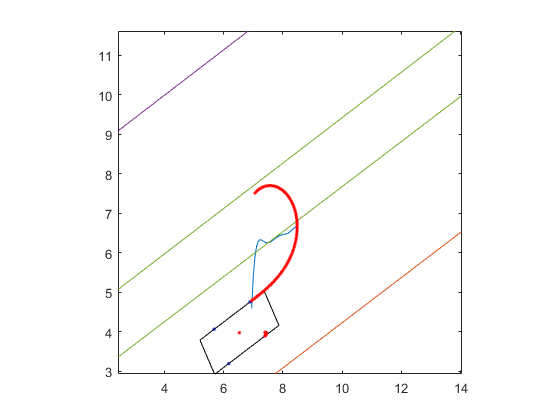

plot(car_body(:,1),car_body(:,2),"k-")

% 实例化对象，组合在结构体里，1为左前，2为左后，3为右后
car.wheel(1)=spot(6.1,0,0.5194235,wheel(1,:));
car.wheel(2)=spot(2,0,0.5194235,wheel(4,:));
car.wheel(3)=spot(2,0,0.5194235,wheel(3,:));
car.wheel(4)=spot(0.2,0,0.5194235,wheel(2,:));
car.body(1)=spot(3,0,0.5194235,car_body(1,:));
car.body(2)=spot(3,0,0.5194235,car_body(4,:));
car.body(3)=spot(3,0,0.5194235,car_body(3,:));
car.body(4)=spot(3,0,0.5194235,[6.53,3.97]);
% c={car.wheel,car.body};

car_xconter=[];
car_yconter=[];
left_degree=0.0011;
right_degree=acot(2/2.8+cot(left_degree));
for i =1:4
    p1.x(i)=kuaiD(i,1);
    p1.y(i)=kuaiD(i,2);
end



while 1
    if car.wheel(4).direction>0.5194235+pi
        break
    end
    
    [x0,y0]=Steering_center(car.wheel(1).position,car.wheel(4).position,left_degree+car.wheel(1).direction,right_degree+car.wheel(4).direction);
    k_car=(car.wheel(1).position(2)-car.wheel(4).position(2))/(car.wheel(1).position(1)-car.wheel(4).position(1));
    
    r1=norm(car.wheel(1).position-[x0,y0]);
    
    car.wheel(1).direction=car.wheel(1).direction+left_degree;
    car.wheel(4).direction=car.wheel(4).direction+right_degree;
    car.wheel(1).forward(0.01);car.wheel(4).forward(0.01);

    
    
    plot(car.wheel(4).position(1),car.wheel(4).position(2),"r.")
    plot(car.wheel(1).position(1),car.wheel(1).position(2),"r.")
    
    car_xconter=[car_xconter,car.wheel(1).position(1)];
    car_yconter=[car_yconter,car.wheel(1).position(2)];
    
    
    if 0.5127-left_degree>0.0011
        left_degree=left_degree+0.0011;
        right_degree=acot(2/2.8+cot(left_degree));
    else
        left_degree=0.5127
        right_degree=acot(2/2.8+cot(left_degree));
    end
    
end
axis square


figure(2)
plot(car_xconter(:),car_yconter(:),"b.")
axis square
hold on
maxx=find()
p = polyfit(car_xconter,car_yconter,6);

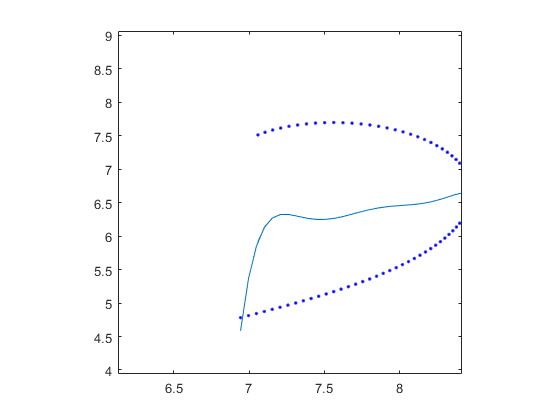

y1 = polyval(p,car_xconter);
plot(car_xconter,y1)





% while 1
%     [x0,y0]=Steering_center(car.wheel(2).position,car.wheel(3).position,car.wheel(1).position,degree);
%     
%     for i=1:3
%         car.body(i).direction=tangent([x0,y0],car.body(i).position,car.body(i).speed,0.1);
%         car.wheel(i).direction=tangent([x0,y0],car.wheel(i).position,car.wheel(i).speed,0.1);
%         car.body(i).forward(0.1);car.wheel(i).forward(0.1);
%         p2.x(i)=car.body(i).position(1);p2.y(i)=car.body(i).position(2);
%         plot(car.wheel(i).position(1),car.wheel(i).position(2),"r.")
%     end
%     
%     if 0.5127-degree>0.0044
%         degree=degree+0.0044
%     else
%         degree=0.5124
%     end
%     
%     mind = min_dist_between_two_polygons(p1,p2,0)
%     if mind <=0.4
%         break
%     end
% end